folder_where_RFTtoolbox_is_saved = 'C:/Users/qyc71/Documents/2022-2023 courses/Rotation winter/RFTtoolbox';
addpath(genpath(folder_where_RFTtoolbox_is_saved))

1D convolution fields

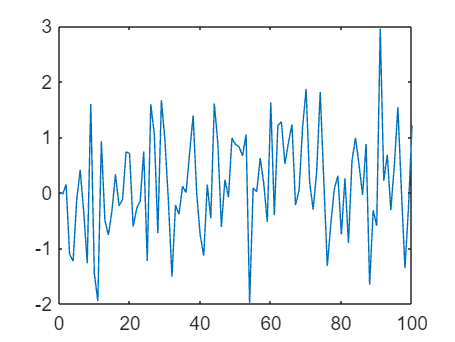

ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
              YData: [-0.0309 0.1520 -1.1058 -1.2262 -0.1408 0.4145 -0.3401 -1.2648 1.5971 -1.4471 -1.9466 0.9293 -0.4958 -0.7629 -0.3224 0.3313 -0.2330 -0.1253 0.7401 0.7070 -0.6100 -0.2859 -0.1457 0.7416 -1.2244 1.5937 1.0575 -0.7254 1.6683 0.9556 … ]

  Show 

clf; nvox = 100; resadd = 10; xvals = 1:nvox;
FWHM = 5; lat_data = wfield([nvox,1]); % a white Gaussian field
plot(lat_data)

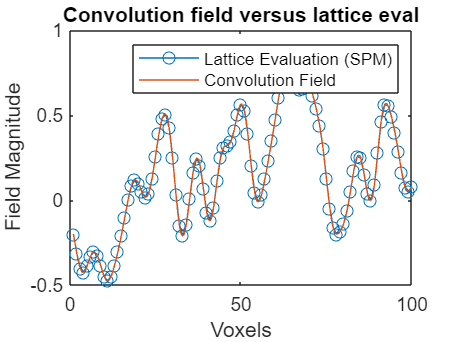

lattice_field = fconv(lat_data.field, FWHM); % default is Gaussian kernal?
params = ConvFieldParams(FWHM, resadd, 0); % ? as above
cfield = convfield( lat_data, params );
% what parameters are needed for a field and a kernal?
% plots
plot(xvals, lattice_field, 'o-')
hold on
plot(cfield);
title('Convolution field versus lattice eval')
xlabel('Voxels'); ylabel('Field Magnitude')
legend('Lattice Evaluation (SPM)', 'Convolution Field')

% local maxima (x and y)
peak_x_vec = [];
peak_y_vec = [];
peak_x = cfield.xvals{1}(lmindices(cfield.field));
if peak_x ~= 1 && peak_x ~= 10
    peak_x_vec = [peak_x_vec, peak_x];
    peak_y_vec = [peak_y_vec, cfield.field(lmindices(cfield.field))];
end

% all peaks
cfield.xvals{1}(lmindices(cfield.field, 'all'));
cfield.field(lmindices(cfield.field, 'all'));
% top 2
cfield.xvals{1}(lmindices(cfield.field, 2));
cfield.field(lmindices(cfield.field, 2));

Simulations, exlude points on the boundry

clf; M = 1000; 
nvox = 100; resadd = 10; xvals = 1:nvox;
FWHM = 2;
peak_x_vec = [];
peak_y_vec = [];
for i = 1:M
    lat_data = wfield([nvox,1]);
    params = ConvFieldParams(FWHM, resadd, 0);
    cfield = convfield( lat_data, params);
    peak_x = cfield.xvals{1}(lmindices(cfield.field));
    if peak_x ~= 1 && peak_x ~= nvox
        peak_x_vec = [peak_x_vec, peak_x];
        peak_y_vec = [peak_y_vec, cfield.field(lmindices(cfield.field))];
    end
end

%histfit(max_y_vec)

Peak (nvox=1000, FWHM = ..., decrease M maybe)

FWHM=1

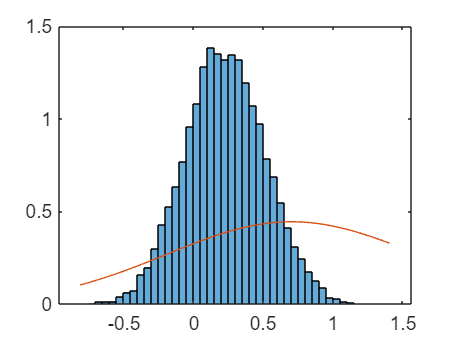

clf; M = 100; 
nvox = 1000; resadd = 10; xvals = 1:nvox;
FWHM = 3;
peak_x_vec = [];
peak_y_vec = [];
for i = 1:M
    lat_data = wfield([nvox,1]);
    params = ConvFieldParams(FWHM, resadd, 0);
    [cfield, ss] = convfield(lat_data, params);
    cfield.field = cfield.field/sqrt(ss);
    peak_x = cfield.xvals{1}(lmindices(cfield.field,'all'));
    peak_y = transpose(cfield.field(lmindices(cfield.field, 'all')));
    if ismember(1,peak_x)
        peak_x = peak_x(2:length(peak_x));
        peak_y = peak_y(2:length(peak_y));
    end
    if ismember(nvox,peak_x)
        peak_x = peak_x(1:(length(peak_x)-1));
        peak_y = peak_y(1:(length(peak_y)-1));
    end
    peak_x_vec = [peak_x_vec, peak_x];
    peak_y_vec = [peak_y_vec, peak_y];
end
% N=1, k=1, theoretical density
k = 1;
x = (0:1000)/1000*range(peak_y_vec) + min(peak_y_vec);
thm_density = sqrt(3-k^2)/sqrt(6*pi)*exp(-3*x.^2/(2*(3-k^2)))...
    + 2*k*x*sqrt(pi)/sqrt(6).*normpdf(x)...
    .*normcdf(k*x/sqrt(3-k^2)); % checked

% how to plot density over histogram?
histogram(peak_y_vec, 'Normalization','pdf')
hold on
plot(x, thm_density)

% integral(thm_density, -2, 4)

FWHM=1.5

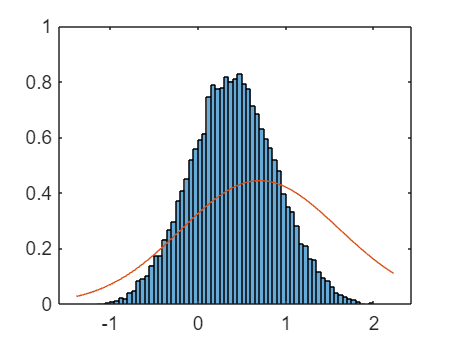

clf; M = 100; 
nvox = 1000; resadd = 10; xvals = 1:nvox;
FWHM = 1.5;
peak_x_vec = [];
peak_y_vec = [];
for i = 1:M
    lat_data = wfield([nvox,1]);
    params = ConvFieldParams(FWHM, resadd, 0);
    [cfield, ss] = convfield(lat_data, params);
    cfield.field = cfield.field/sqrt(ss);
    peak_x = cfield.xvals{1}(lmindices(cfield.field,'all'));
    peak_y = transpose(cfield.field(lmindices(cfield.field, 'all')));
    if ismember(1,peak_x)
        peak_x = peak_x(2:length(peak_x));
        peak_y = peak_y(2:length(peak_y));
    end
    if ismember(nvox,peak_x)
        peak_x = peak_x(1:(length(peak_x)-1));
        peak_y = peak_y(1:(length(peak_y)-1));
    end
    peak_x_vec = [peak_x_vec, peak_x];
    peak_y_vec = [peak_y_vec, peak_y];
end
% N=1, k=1, theoretical density
k = 1;
x = (0:1000)/1000*range(peak_y_vec) + min(peak_y_vec);
thm_density = sqrt(3-k^2)/sqrt(6*pi)*exp(-3*x.^2/(2*(3-k^2)))...
    + 2*k*x*sqrt(pi)/sqrt(6).*normpdf(x)...
    .*normcdf(k*x/sqrt(3-k^2)); % checked

% how to plot density over histogram?
histogram(peak_y_vec, 'Normalization','pdf')
hold on
plot(x, thm_density)

% integral(thm_density, -2, 4)

2d

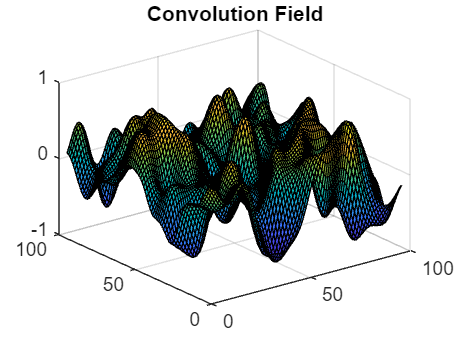

clf;Dim = [20,20]; D = length(Dim); resadd = 4; FWHM = 2;
lat_data = wfield(Dim);
params = ConvFieldParams([FWHM,FWHM], resadd, 0);
fine_data = convfield( lat_data, params);
surf(fine_data.field)
title('Convolution Field')

Simulation

clf; M = 1000; 
Dim = [20,20]; D = length(Dim); resadd = 4; FWHM = 2;
lat_data = wfield(Dim);
params = ConvFieldParams([FWHM,FWHM], resadd, 0);
peak_x_mat = [];
peak_y_vec = [];
for i = 1:M
    lat_data = wfield(Dim);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    peak_x = fine_data.xvals{1}(lmindices(fine_data.field));
    peak_x_mat = [peak_x_mat; peak_x];
    temp = lmindices(fine_data.field);
    peak_y_vec = [peak_y_vec; fine_data.field(temp(1), temp(2))];
end
%histfit(max_y_vec)

Peak

FWHM=1

clf; M = 1000; 
Dim = [20,20]; D = length(Dim); resadd = 4; FWHM = 1;
lat_data = wfield(Dim);
params = ConvFieldParams([FWHM,FWHM], resadd, 0);
peak_x_mat = [];
peak_y_vec = [];
for i = 1:M
    lat_data = wfield(Dim);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    peak_x = fine_data.xvals{1}(lmindices(fine_data.field, 'all'));
    peak_x_mat = [peak_x_mat, peak_x];
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            peak_y_vec = [peak_y_vec;...
            fine_data.field(temp(1, j), temp(2, j))];
        end
        
    end
end

k = 1;
x = (0:1000)/1000*range(peak_y_vec) + min(peak_y_vec);
thm_density = sqrt(3)*k^2*(x.^2-1).*normpdf(x)...
    .*normcdf(k*x/sqrt(2-k^2)) + k*x*sqrt(3*(2-k^2))/(2*pi).*...
    exp(-x.^2/(2-k^2)) + sqrt(6)/sqrt(pi*(3-k^2))...
    *exp(-3*x.^2/(2*(3-k^2)))...
    .*normcdf(k*x/sqrt(3-k^2)/sqrt(2-k^2));

histogram(peak_y_vec, 'Normalization', 'probability')
hold on
plot(x, thm_density)

FWHM=2

clf; M = 1000; 
Dim = [20,20]; D = length(Dim); resadd = 4; FWHM = 2;
lat_data = wfield(Dim);
params = ConvFieldParams([FWHM,FWHM], resadd, 0);
peak_x_mat = [];
peak_y_vec = [];
for i = 1:M
    lat_data = wfield(Dim);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    peak_x = fine_data.xvals{1}(lmindices(fine_data.field, 'all'));
    peak_x_mat = [peak_x_mat, peak_x];
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            peak_y_vec = [peak_y_vec;...
            fine_data.field(temp(1, j), temp(2, j))];
        end
        
    end
end

k = 1;
x = (0:1000)/1000*range(peak_y_vec) + min(peak_y_vec);
thm_density = sqrt(3)*k^2*(x.^2-1).*normpdf(x)...
    .*normcdf(k*x/sqrt(2-k^2)) + k*x*sqrt(3*(2-k^2))/(2*pi).*...
    exp(-x.^2/(2-k^2)) + sqrt(6)/sqrt(pi*(3-k^2))...
    *exp(-3*x.^2/(2*(3-k^2)))...
    .*normcdf(k*x/sqrt(3-k^2)/sqrt(2-k^2));

histogram(peak_y_vec, 'Normalization', 'probability')
hold on
plot(x, thm_density)